clear all
[s, fs] = audioread("1_8000.wav");
rt = 0.4;
N = fs * 4;
d = fs * rt;
decayrate = 10;
predelay = 60 * 1e-3 * fs;
h = (exp(-decayrate * linspace(0,rt,d)) .* randn([1, d]))';
h(1:predelay-1) = 0;
h(predelay) = 1;
h = h / norm(h);
x = conv(s, h);


## displaying

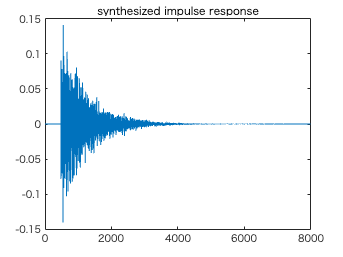

figure; plot(h); title("synthesized impulse response")

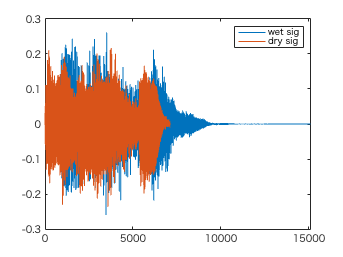

figure
plot(x, "DisplayName", "wet sig"); hold on; 
plot(s, "DisplayName", "dry sig"); legend();

## block processing

% partition settings
function blocks = frame_signal(x, M, a, d)
    % x: 入力信号（一次元ベクトル）
    % M: フレーム長
    % a: ホップサイズ
    % blocks: M行×N列の行列（各列が1ブロック）

    x = x(:);  % 縦ベクトルに変換
    L = length(x);
    numFrames = floor((L - M) / a) + 1;

    blocks = zeros(M, numFrames);
    windowFcn = hamming(M, "symmetric");
    x = buffer(x, )

    l = M - d + 1;
    for i = 1:numFrames
        startIdx = (i - 1) * a + 1;
        temp = x(startIdx : startIdx + M - 1);
        temp = temp .* windowFcn;
        blocks(:, i) = temp;
        if i > 1
            Syl = [convmtx(frame_pre, l) convmtx(temp, l)];
        end
        frame_pre = temp;
    end
end

M = 1024*4; a = M / 2;
blocks = frame_signal(x, M , a, d);